MA-1006 

Grupo: 01

Estudiante: Josef Ruzicka

Carnet: B87095

# Tarea #2

**Instrucciones:**				

- Todo debe trabajarlo en este .mlx

- Si realiza procesos a mano puede agregar las imágenes insertándolas.

- Recuerde que puede consultar con el docente si tiene dudas. 

- Para las M-funciones procure comentar para indicar que es lo que se hace en cada paso. 

- El total de puntos es de 100. 

## Ejercicios

## **#1 (30 puntos)**

$\texttt{MATLAB}$ incluye la función $\texttt{invhilb(n)}$para calcular la inversa de la matriz de Hilbert (investigue sobre esta matriz) de tamaño $n \times n$. Para $\texttt{n=1:20}$ grafique el error absoluto


$$\| \texttt{hilb(n)*invhilb(n)-eye(n)}\|_{\infty}$$


en función de $n$, donde $\texttt{eye(n)}$ representa la matriz identidad de tamaño $n \times n$. Concluya que la función $\texttt{invhilb}$ no es confiable para valores de $n \geq 10.$ 

**Nota:** utilice en la graficación la escala logarítmica para el eje vertical, con $\texttt{semilogy}$. 

% De https://la.mathworks.com/help/symbolic/hilbert-matrices-and-their-inverses.html?s_tid=mwa_osa_a
% Conseguimos la explicación de que la cada entrada de la matriz de Hilbert
% se obtiene de H[i][j] = 1/(i + j - 1). Tambien se refieren a la matriz
% como una  'ill-conditioned', por su elevado condition number, lo que se
% refiere a que es una matriz que va a dar resultados no tan deseados a la
% hora de utilizar una función sobre la misma.

disp('Calculando errores para cada matriz de Hilbert de tamanos 1x1 hasta 20x20')

Calculando errores para cada matriz de Hilbert de tamanos 1x1 hasta 20x20


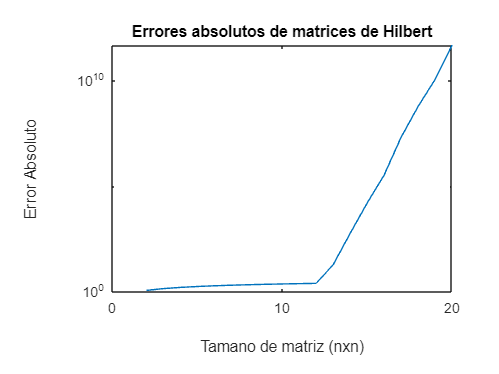

errors = zeros(1, 20);
for n = 1:20
    H = hilb(n);
    % Condition number para revisar si la matrix es ill conditiones o well conditioned.
    cond(H);     
    invH = H*invhilb(n);
    errors(n) = norm(H*invH-eye(n), "inf");
end
% Plotteo
semilogy(errors)
title('Errores absolutos de matrices de Hilbert');
xlabel('Tamano de matriz (nxn)');
ylabel('Error Absoluto');


% Al observar el grafico, es posible notar que a partir de aproximadamente
% la iteracion que corresponde a n=11 el erorr absoluto comienza a aumentar
% de forma exponencial.

## #2 (40 puntos)

Considere la matriz tridiagonal (la puede generar usando $\texttt{Tridiagxb(m)}$en la seccion de Funciones):

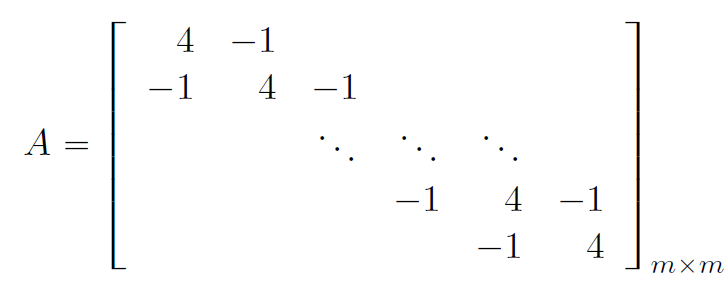

Considere $\mathbf{b}$ de tal manera que $\mathbf{x^*} = (1,...,1)^{\texttt{t}} \in \mathbb{R}^m$ es la solución exacta del sistema $\mathbf{Ax}= \mathbf{b}.$ 

- Utilice $\texttt{Tridiagxb(m)}$para calcular la matriz $\mathbf{A}$ y el vector $\mathbf{x^*}$ dado el input $m$. Imprima ellos casos $m=1:20$.

- Para $m=1000, \quad \mathbf{x}^{(0)}$ vector nulo, grafique el error $\|\mathbf{x}^{(k)}-\mathbf{x^*} \|_{\infty}$ en función del número de iteraciones $k$ para los métodos de Jacobi y Gauss-Seidel hacia adelante. Su gráfica deberá parecerse a la siguiente:

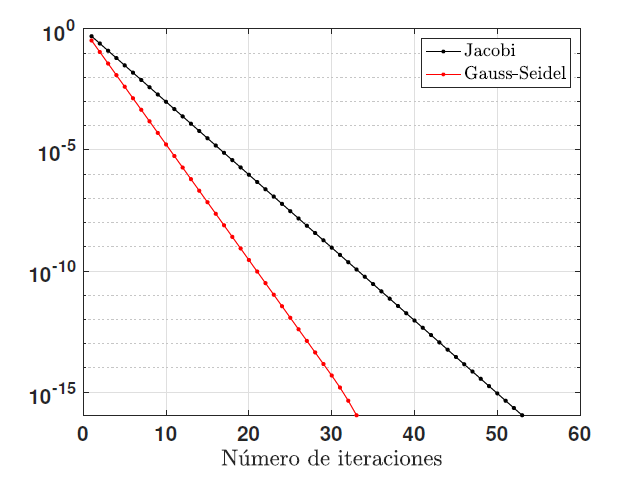

disp('Computando pregunta 2, para observar las impresiones del')

Computando pregunta 2, para observar las impresiones del


disp('punto 1) elimine el ; de la linea 29. Si por alguna razon')

punto 1) elimine el ; de la linea 29. Si por alguna razon


disp('un grafico aparece en blanco, hagale click y presione')

un grafico aparece en blanco, hagale click y presione


disp('open in Figure Window')

open in Figure Window


% 1) Profe perdon pero es muy incomodo imprimir estos 20 casos. les puse ;
for m = 1:20   
    [A, xsol, b] = Tridiagxb(m);
end

% 2) Caso 1000
[A, xsol, b] = Tridiagxb(1000);
x_zeros = zeros(1, 1000)';
x_ones = ones(1, 1000)';

% Creacion de arreglos
% Tome los cell arrays de aqui https://la.mathworks.com/help/matlab/ref/cell.html
% porque no supe como hacer arreglos de arreglos, mi idea era hacer
% x_jac = zeros(60, 1000, 1) pero luego no logre compatibilidad con
% (1000, 1)
kmax = 60; %tomamos 60 basado en la grafica del prof.
x_jac = cell(kmax, 1);
x_gsf = cell(kmax, 1);

% Errors
errors_jac = [1, kmax];
errors_gsf = [1, kmax];

for k = 1:kmax
    x_jac{k} = zeros(1000, 1);
    x_gsf{k} = zeros(1000, 1);
end

% Probar creacion de arreglos
%size(x_jacs(1))
%size(JacobiM(A, b, x_zeros, k))

% Computo de las aproximaciones
for k = 1:kmax
    % Jacobi
    x_jac{k} = JacobiM(A, b, x_zeros, k);
    
    % Gauss-Seidel
    x_gsf{k} = GaussSeidelFM(A, b, x_zeros, k);
end

% Calculo del error
for e = 1:kmax  
    errors_jac(e) = norm(x_jac{e} - xsol, "inf");
    errors_gsf(e) = norm(x_gsf{e} - xsol, "inf");
end

% Ploteo. ver https://la.mathworks.com/help/matlab/ref/semilogy.html#bspllbx_sep_mw_3a76f056-2882-44d7-8e73-c695c0c54ca8
%Y = 10.^(-15:0);
%Y = zeros(1, 60);
%Y(1) = 10^(-15);
X = 1:60;
%semilogy(errors_jac)
%semilogy(errors_gsf)
semilogy(X, errors_jac, '-.k' ,X ,errors_gsf, '-.r' )
title('Errores absolutos de aproximaciones de Jacobi y Gauss-Seidel');
xlabel('Iteraciones');
ylabel('Error Absoluto');
legend('Jacobi','Gauss-Seidel','Location','northeast')




%%% Puntos extra %%%
disp('Calculo de error dentro de funcion')

Calculo de error dentro de funcion


tic
new_jac_errors = [1, kmax];
new_gsf_errors = [1, kmax];
for k = 1:kmax
    % Jacobi
    [x_jac{k}, new_jac_errors(k)] = JacobiM_err(A, b, x_zeros, k, xsol);
     % Gauss-Seidel
    [x_gsf{k}, new_gsf_errors(k)] = GaussSeidelFM_err(A, b, x_zeros, k, xsol);
end
toc

Elapsed time is 27.553880 seconds.



disp('Calculo de error fuera de funcion')

Calculo de error fuera de funcion


tic
for k = 1:kmax
    % Jacobi
    x_jac{k} = JacobiM(A, b, x_zeros, k);
     % Gauss-Seidel
    x_gsf{k} = GaussSeidelFM(A, b, x_zeros, k);
end

% Calculo del error
for e = 1:kmax  
    errors_jac(e) = norm(x_jac{e} - xsol, "inf");
    errors_gsf(e) = norm(x_gsf{e} - xsol, "inf");
end

toc

Elapsed time is 28.052690 seconds.




% Para verificar correctitud
%new_jac_errors
%errors_jac
%new_gsf_errors
%errors_gsf

## **#3 (30 puntos)**

Considere la siguiente matriz:

A=[-1 -1 1; 
    1 3 3; 
   -1 -1 5;
    1 3 7]

A =     -1    -1     1
     1     3     3
    -1    -1     5
     1     3     7


Calcule la factorizacion QR **paso a paso**, tal como aparece en la presentacion del profesor Filander sobre resolucion de sistemas lineales, utilizando el codigo que se adjunta en la seccion de Funciones (abajo). Por ejemplo, en el primer paso se tiene que

% Paso 1
x1 = A(:,1) % Primer vector columna

x1 =     -1
     1
    -1
     1


format rat 
[u1,H1] = HMat(x1) % vector u1 aosciado a x1, matriz H1 asociada a u1

u1 =       -3       
       1       
      -1       
       1       


H1 =       -1/2            1/2           -1/2            1/2     
       1/2            5/6            1/6           -1/6     
      -1/2            1/6            5/6            1/6     
       1/2           -1/6            1/6            5/6     


H1A = H1*A

H1A =        2              4              2       
       *              4/3            8/3     
       *              2/3           16/3     
       *              4/3           20/3     




% Paso 2
x2 = H1A(2:end, 2) % En este slice tomamos a partir de la segunda fila nada mas.

x2 =        4/3     
       2/3     
       4/3     


[u2,H2] = HMat(x2)

u2 =       10/3     
       2/3     
       4/3     


H2 =       -2/3           -1/3           -2/3     
      -1/3           14/15          -2/15    
      -2/3           -2/15          11/15    



%%%% El bloque de codigo que sigue fue un intento fallido
% Para agregar filas y columnas utilizamos las respuestas de este foro
% https://la.mathworks.com/matlabcentral/answers/487210-how-to-add-a-row-and-column-to-a-matrix
%H2(end+1, :) = 0
%H2([1 end], :) = H2([end 1], :)
%H2(:, end+1) = 0 % Agregamos columna y fila de 0s y un 1 en el [1, 1]
%H2(:, [0 end]) = H2(:, [end 0])
%H2(1,1) = 1 % Agregamos el 1 de la diagonal
%%%% 

% Creamos la identidad y le agregamos H2.
temp = eye(4);
temp(2:end, 2:end) = H2;
H2 = temp

H2 =        1              0              0              0       
       0             -2/3           -1/3           -2/3     
       0             -1/3           14/15          -2/15    
       0             -2/3           -2/15          11/15    


H2H1A = H2*H1A

H2H1A =        2              4              2       
       *             -2             -8       
       *              *             16/5     
       *              *             12/5     




% Paso 3
x3 = H2H1A(3:end, 3)

x3 =       16/5     
      12/5     


[u3,H3] = HMat(x3)

u3 =       36/5     
      12/5     


H3 =       -4/5           -3/5     
      -3/5            4/5     


temp = eye(4);
temp(3:end, 3:end) = H3;
H3 = temp

H3 =        1              0              0              0       
       0              1              0              0       
       0              0             -4/5           -3/5     
       0              0             -3/5            4/5     


H3H2H1A = H3*H2H1A % Esto es R

H3H2H1A =        2              4              2       
       *             -2             -8       
       *              *             -4       
       *              *              0       


Q = H1*H2*H3

Q =       -1/2           -1/2            1/2            1/2     
       1/2           -1/2            1/2           -1/2     
      -1/2           -1/2           -1/2           -1/2     
       1/2           -1/2           -1/2            1/2     


format default

# **Funciones**

***Tridiagxb***

function [A, xsol, b] = Tridiagxb(m)
% Input: m dimensión de la matriz
% Outputs: A tridiagonal específica
% vector solución x=[1,...,1]' y vector b

E=-ones(m-1,1);
A = 4*eye(m) + diag(E,1) + diag(E,-1);

xsol =  ones(m,1);

b = A*xsol;

end 

***Jacobi versión matricial***

function x_jac = JacobiM(A,b,x0, k)
% Input: Matriz A, vector b, k iteraciones
% output: x aproximación k-ésima x^(k)

D=diag(diag(A));
U=triu(A)-D; % = triu(A,1)
L=tril(A)-D; % = tril(A,-1)

if k==0
    x=x0;

else
    for i = 1:k
        x = inv(D)*(b-(L+U)*x0);
        x0 = x;
        k = k+1;
    end
end

x_jac=x;
end

% Version que calcula error por puntos extra.
function [x_jac, err] = JacobiM_err(A,b,x0,k, xsol)
% Input: Matriz A, vector b, k iteraciones
% output: x aproximación k-ésima x^(k)

D=diag(diag(A));
U=triu(A)-D; % = triu(A,1)
L=tril(A)-D; % = tril(A,-1)
err = [1, k]; % array de errores
if k==0
    x=x0;

else
    for i = 1:k
        x = inv(D)*(b-(L+U)*x0);
        x0 = x;
        k = k+1;
    end
end

x_jac=x;
err = norm(x_jac - xsol, 'inf');
end

***Gauss-Seidel adelante versión matricial***

function x_gsf = GaussSeidelFM(A,b,x0, k)
% Input: Matriz A, vector b, k iteraciones
% output: x aproximación k-ésima x^(k)

D=diag(diag(A));
U=triu(A)-D;
L=tril(A)-D;

if k==0             % Noten que en el for se descarta x0, por eso hay que
    x=x0;           % "recuperarlo"

else
    for i=1:k
        x = inv(L+D)*(b-U*x0);
        x0 = x;
        k = k+1;
    end
end

x_gsf=x;
end

% Version que calcula error por puntos extra.
function [x_gsf, err]= GaussSeidelFM_err(A,b,x0, k, xsol)
% Input: Matriz A, vector b, k iteraciones
% output: x aproximación k-ésima x^(k)

D=diag(diag(A));
U=triu(A)-D;
L=tril(A)-D;

if k==0             % Noten que en el for se descarta x0, por eso hay que
    x=x0;           % "recuperarlo"

else
    for i=1:k
        x = inv(L+D)*(b-U*x0);
        x0 = x;
        k = k+1;
    end
end

x_gsf=x;
err = norm(x_gsf - xsol, 'inf');
end

***QR Householder***

function [Q,R] = QRHouse(A)
    [m,n] = size(A);
    R = A;
    Q = eye(m);
    for k = 1:n
        x = zeros(m-k+1,1);
        x(1:m-k+1,1) = R(k:m,k);
        e1 = zeros(m-k+1,1);
        e1(1,1) = 1;
        u = x + sign(x(1,1)) * norm(x) * e1;
        Htecho = eye(m-k+1,m-k+1)-2*(u*u')/(u'*u);
        H = [eye(k-1), zeros(k-1, m-k+1);
              zeros(m-k+1, k-1), Htecho];
        R = H*R;
        Q = Q*H;
    end
end

***Matriz de Householder asociada a un vector no nulo***

function [u, H] = HMat(x)
u = x + sign(x(1)) * [norm(x); zeros(length(x)-1,1)];
H = eye(length(x)) - 2*(u*u')/(u'*u);
end
